Forma cuadrática 2D y 3D

Qf(x)=1/2(a*x^2)-(b*x)+c

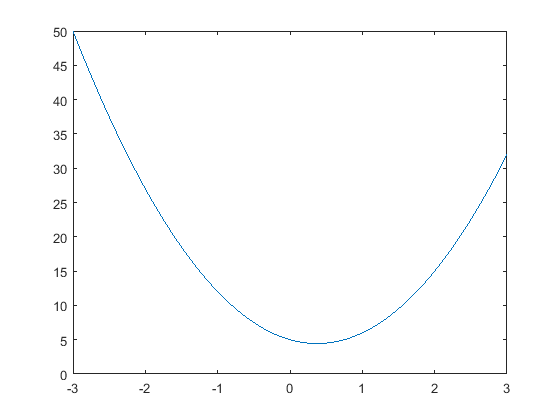


Qf= @(a,b,c,x) 1/2*(a*x.^2)-(b*x)+c;
a=8;
b=3;
c=5;
x=linspace(-3, 3, 100);
f=Qf(a,b,c,x);
plot(x,f);

Sabemos que el punto crítio de Qf(x) está en Qf'(x)=0

Qf'(x)=a*x-b;

El punto crítico es  x=b/a

Y la función en ese mínimo es igual a : Qf(b/a)=1/2*(b.^2/a)+c

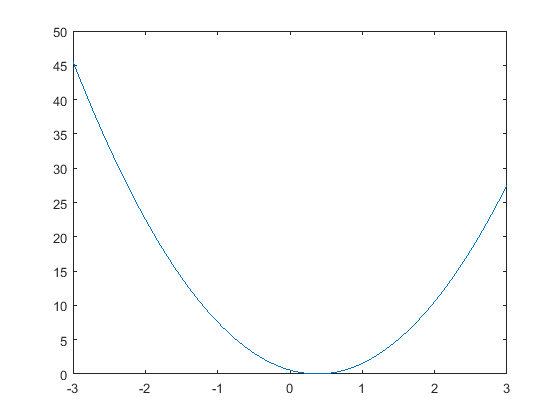

c=1/2*((b^2)/a);
f=Qf(a,b,c,x);
plot(x,f);

Forma cuadrática en 3 dimensiones

Qf=(1/2)*(x'*A*x) - b'*x + c

A: matriz de 2x2

Qf = @(A,b,c,x1,x2) (1/2)*((A(1,1)*x1.^2) + (A(1,2) + A(2,1))*(x1.*x2) + A(2,2)*x2.^2)...
     - (b(1)*x1 + b(2)*x2) + c;
A = [1,0;0,2];
b = [1;2];
x = A\b;

Gráfica

x1=0:0.1:2;
x2=0:0.1:2;
[X1 X2]=meshgrid(x1,x2);
f=Qf(A,b,c,X1,X2);
surf(X1,X2,f)%para crear la parábola en 3D
[cs,h]=contour(x1,x2,f)%para crear las curbas de nivel 

cs =    -0.8000    1.3071    1.3000    1.2000    1.1000    1.0000    0.9000    0.8000    0.7000    0.6929    0.6000    0.5611    0.5000    0.4955    0.4773    0.4955    0.5000    0.5611    0.6000    0.6929    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.3071    1.4000    1.4389    1.5000    1.5045    1.5227    1.5045    1.5000    1.4389    1.4000    1.3071   -0.6000    1.4167    1.4000    1.3000    1.2000    1.1000    1.0000    0.9000    0.8000    0.7000    0.6000    0.5833
   37.0000    0.7000    0.6964    0.6607    0.6393    0.6321    0.6393    0.6607    0.6964    0.7000    0.7650    0.8000    0.8917    0.9000    1.0000    1.1000    1.1083    1.2000    1.2350    1.3000    1.3036    1.3393    1.3607    1.3679    1.3607    1.3393    1.3036    1.3000    1.2350    1.2000    1.1083    1.1000    1.0000    0.9000    0.8917    0.8000    0.7650    0.7000   57.0000    0.5000    0.4932    0.4614    0.4386    0.4250    0.4205    0.4250    0.4386    0.4614    0.4932    

h =   Contour with properties:

    LineColor: 'flat'
    LineStyle: '-'
    LineWidth: 0.5000
         Fill: 'off'
    LevelList: [-0.8000 -0.6000 -0.4000 -0.2000 0 0.2000 0.4000]
        XData: [0 0.1000 0.2000 0.3000 0.4000 0.5000 0.6000 0.7000 0.8000 0.9000 1 1.1000 1.2000 1.3000 1.4000 1.5000 1.6000 1.7000 1.8000 1.9000 2]
        YData: [0 0.1000 0.2000 0.3000 0.4000 0.5000 0.6000 0.7000 0.8000 0.9000 1 1.1000 1.2000 1.3000 1.4000 1.5000 1.6000 1.7000 1.8000 1.9000 2]
        ZData: [21×21 double]

  Show all properties


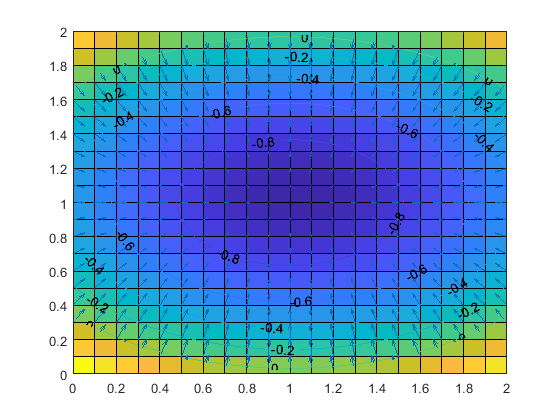

clabel(cs,h)
hold on
[fx1,fx2]=gradient(f,0.25);
quiver(x1,x2,-fx1,-fx2)